clear all;
close all;

%first LCG
a = 18;
m = 101;
k = 5*m;
x = zeros(1,k);
x(1) = 31;

for i=2:k
    x(i) = mod(a*x(i-1),m);
end
find(x == x(1)) %find when the seed appears again

ans =      1   101   201   301   401   501


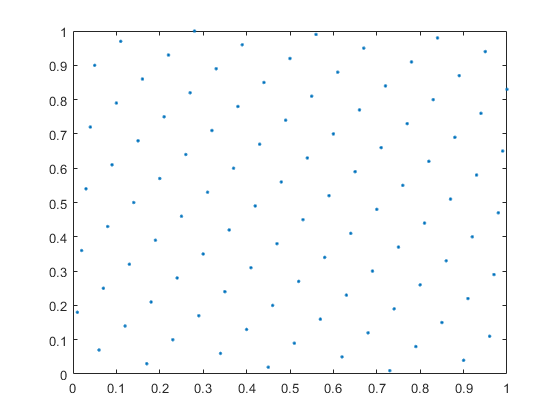

x = x/max(x);

xs = lagmatrix(x,-1);
plot(x,xs,'.');

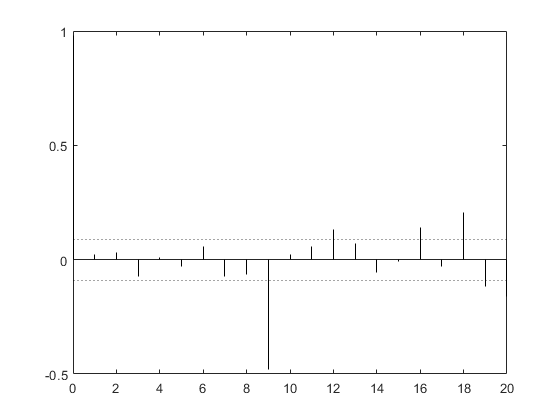

[acf,lags,bounds] = autocorr(x);
stem(lags,acf,'Marker','none','Color','k');
hold on
yline(bounds(1),':k');
yline(bounds(2),':k');
hold off


%second LCG
a = 2;
% m is the same
x = zeros(1,k);
x(1) = 31;
for i=2:k
    x(i) = mod(a*x(i-1),m);
end
find(x == x(1)) %find when the seed appears again

ans =      1   101   201   301   401   501


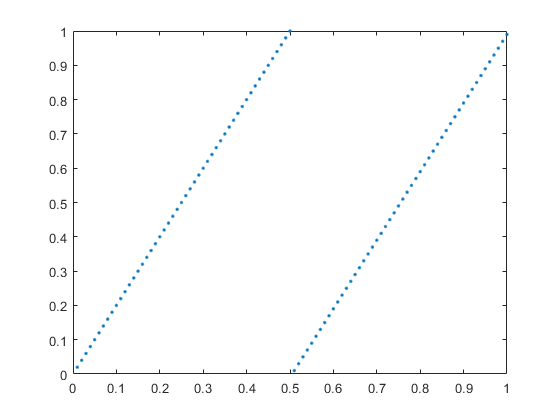

x = x/max(x);

xs = lagmatrix(x,-1);
plot(x,xs,'.');

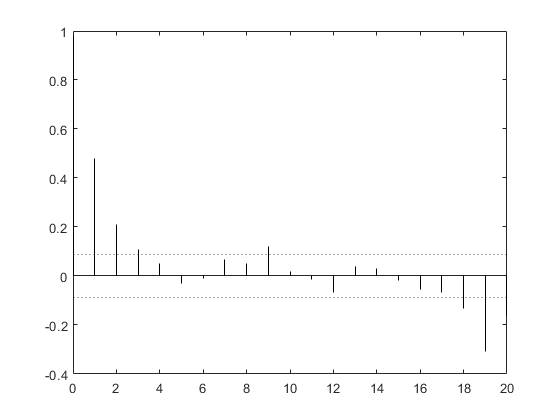

[acf,lags,bounds] = autocorr(x);
stem(lags,acf,'Marker','none','Color','k');
hold on
yline(bounds(1),':k');
yline(bounds(2),':k');
hold off